# MATLAB Exercise 6.10:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Design an elliptic analog bandpass filter to meet the specifications below.

 
$$\left.\begin{array}{r c l}
-3\le\left|H\left(f\right)\right|_{dB}\le 0 & \textrm{for} & 2\le f\le 3\;\textrm{Hz} \\
\left|H\left(f\right)\right|_{dB}\le -25.0 & \textrm{for} & f \le 1.5\;\textrm{Hz}\;\;\textrm{or}\;\;f\ge 3.5\;\textrm{Hz}
\end{array}$$


Use second-order cascade sections.

% Enter specifications
Rp = 3;
As = 25;
fp = [2,3];         % Passband edge frequencies in Hz
fs = [1.5,3.5];     % Stopband edge frequencies in Hz
Wp = 2*pi*fp;       % Passband edge frequencies in rad/s
Ws = 2*pi*fs;       % Stopband edge frequencies in rad/s
f = [0:0.005:7];    % Set vector of frequencies for graphing
omg = 2*pi*f;

% Design elliptic filter
[N,Wp] = ellipord(Wp,Ws,Rp,As,'s');  % Compute elliptic filter parameters
[zeros,poles,gain] = ellip(N,Rp,As,Wp,'s');  % Design elliptic filter
[sos,gain] = zp2sos(zeros,poles,gain);       % Convert to SOS format
disp('Second-order sections:');

Second-order sections:


[nRows,nCols] = size(sos);
for k = 1:nRows      
  num = sos(k,1:3);      % Numerator polynomial of section k
  den = sos(k,4:6);      % Denominator polynomial of section k
  section = tf(num,den)  % Display system function for section k
end

section =
 
      s + 3.978e-17
  ---------------------
  s^2 + 0.771 s + 347.9
 
Continuous-time transfer function.
Model Properties

section =
 
  s^2 - 3.318e-16 s + 417.7
  -------------------------
    s^2 + 2.389 s + 236.9
 
Continuous-time transfer function.


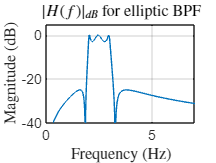

% Graph the dB magnitude
H4dB = dBMagnitudeFromSOS(sos,gain,omg);     % Compute dB magnitude
plot(f,H4dB); grid;
axis([0,7,-40,5]);
set(0,'defaultTextInterpreter','latex');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('$|H(f)|_{dB}$ for elliptic BPF');

set(0,'defaultTextInterpreter','tex');

function HdB = dBMagnitudeFromSOS(sos,gain,omg)
  % Function to compute dB magnitude from SOS matrix.
  [nRows,nCols] = size(sos);               % Get the size of SOS matrix
  HdB = 20*log10(gain)*ones(size(omg));    % Start with gain factor
  for k = 1:nRows      
    num = sos(k,1:3);  % Numerator polynomial of section k
    den = sos(k,4:6);  % Denominator polynomial of section k
    HdB = HdB + dBMagnitude(num,den,omg);  % Add the contribution
  end
end

function HdB = dBMagnitude(num,den,omg)
  % Function to compute dB magnitude from numerator and denominator
  H = freqs(num,den,omg);
  HdB = 20*log10(abs(H));
end